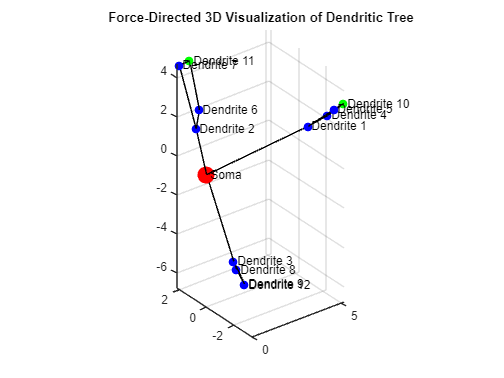

%addpath 'D:/some_fhn_stuff/utils/'
%addpath 'D:/dpl/MATLAB_Sim_and_Analysis/'
addpath 'D:/UNI/CompartmentalFHN/DTreeModelSim'
datasetPath = 'D:/bearing_dpl/padeborn_dataset/Paderborn Bearings';
addpath(genpath(datasetPath));

% Simulation parameters
% h = 0.0001;  % Time increment
tmax = 4;
h = 1e-4;
t = 0:h:tmax;
% Final time value for calculation
% t = 0:h:tmax;  % Time vector

params.Tau = 1200;  % Neural time constant
params.TauR = 1200;  % Recovery time constant
params.gc = 1; % Conductance between compartments
params.NaX = 0.1; % Sodium channel density factor for dendrites
params.alpha = 10;
params.b = 1;

Stim = 1.5*sin(28*2*pi*t);% sig;

initCon = [0.02; 0.02];

% Initilaize Soma
params.NaX = 1;
soma = Dendrite(0, params, initCon);

% dendritic tree model
dTreeModel = DendriteTreeModel();

% Add soma to the tree model (ID = 0 reserved for soma)
dTreeModel = dTreeModel.addDendrite(soma);

params.NaX = .5;
dend = Dendrite(0, params, initCon);
% Add dendrites with IDs
for ID = 1:3
   dend.ID = ID;
   dTreeModel = dTreeModel.addDendrite(dend);
end

%params.NaX = .4;
dend = Dendrite(0, params, initCon);
% Add dendrites with IDs
for ID = 4:9
   dend.ID = ID;
   dTreeModel = dTreeModel.addDendrite(dend);
end

%params.NaX = .1;
dend = Dendrite(0, params, initCon);
% Add dendrites with IDs
for ID = 10:12
   dend.ID = ID;
   dTreeModel = dTreeModel.addDendrite(dend);
end
% Define connections
% dTreeModel = dTreeModel.addConnection(0, [], [1, 4]); % Soma connected to dendrites 1 and 4
% 
% dTreeModel = dTreeModel.addConnection(1, [], 2);
% dTreeModel = dTreeModel.addConnection(2, [], 3);
% 
% dTreeModel = dTreeModel.addConnection(4, [], 5);
% dTreeModel = dTreeModel.addConnection(5, [], 6);

% dTreeModel = dTreeModel.addConnectionStr("0-[1,2,3]");
% dTreeModel = dTreeModel.addConnectionStr("1-[4,5]-10");
% dTreeModel = dTreeModel.addConnectionStr("2-6-7-11");
% dTreeModel = dTreeModel.addConnectionStr("3-[8,9]-12");
% dTreeModel = dTreeModel.addConnectionStr("3-12");
% dTreeModel = dTreeModel.addConnectionStr("8-9");

dTreeModel = dTreeModel.addConnectionStr("0-[1,2,3]");
dTreeModel = dTreeModel.addConnectionStr("1-[4,5]-10");
dTreeModel = dTreeModel.addConnectionStr("2-[6,7]-11");
dTreeModel = dTreeModel.addConnectionStr("3-[8,9]-12");

% External stimulus signal
HealthyGroup = 'N09_M07_F10_K001';
OrGroup = 'N09_M07_F10_KA01';
IrGroup = 'N09_M07_F10_KI07';
ipd = 1; % [1...20]

name = sprintf('%s_%d.mat', OrGroup, ipd);
var_name = sprintf('%s_%d', OrGroup, ipd);

load(name)
t = eval([var_name '.X(2).Data']);
sig = eval([var_name '.Y(7).Data']);

% Resample
targetFs = 64e+3;
h = 1/targetFs;
%[p, q] = rat(targetFs / 64e+3);
%[sig, t] = resample(sig, t, targetFs, p, q, 'pchip');
% Trim
[t, sig] = trim_signal(t, sig, targetFs, tmax);

Stim = sig./rms(sig);

dTreeModel = dTreeModel.addStimuli(10, Stim);
dTreeModel = dTreeModel.addStimuli(11, Stim);
dTreeModel = dTreeModel.addStimuli(12, Stim);

dTreeModel.verify();

dTreeModel.visualizeFDGL(100, 1e-2);

% dTreeModel.visualize3D();

% Build the model with step size 'h'
dTreeModel = dTreeModel.buildModel(h);

% Get initial conditions
% X0 = dTreeModel.getInitCon();

% Solve ODEs using RK4 solver
% [ab, bb, cb] = ButcherTableau.get("RK4");
% solver = rk_solver(ab, bb, cb);

% Verifies tree integrity
dTreeModel.verify();

% Run single step solver
% tic
% [t, Xold] = solver.solve(@(t, x) dTreeModel.computeRHS(t, x), tmax-h, X0, h);
% toc
% 
% tic
% [t, Xsparse] = solver.solve(@(t, x) dTreeModel.sparseRHS(t, x), tmax-h, X0, h);
% toc

tic
[t, X] = dTreeModel.RK4CPP(tmax-h);
toc

Elapsed time is 3.506015 seconds.


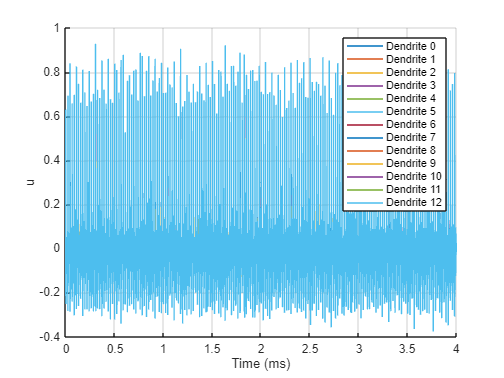


% Plot results
numDendrites = dTreeModel.numDendrites;
u_values = zeros(numDendrites, length(t));

for i = 1:numDendrites
    idx = (i - 1)*2 + 1;
    u_values(i, :) = X(idx, :);
end

% Plot u variables for each dendrite
figure;
hold on;
for i = 1:numDendrites
    plot(t, u_values(i, :));
end
xlabel('Time (ms)');
ylabel('u');
legend(arrayfun(@(x) sprintf('Dendrite %d', dTreeModel.dendrites(x).ID), 1:numDendrites, 'UniformOutput', false));
grid on;
hold off;

% Extract membrane potentials for each dendrite
temp = zeros(numDendrites, length(t));
for i = 1:numDendrites
    idx = (i - 1)*2 + 1; % Index for 'u' variable of dendrite i
    for j = 1:length(temp)
        % if X(idx, j) > 0.4
            temp(i, j) = X(idx, j);
        % else
        %     temp(i, j) = 0;
        % end
    end
end

% Generate labels for y-axis
labels = cell(numDendrites, 1);
for i = 1:numDendrites
    ID = dTreeModel.dendrites(i).ID;
    if ID == 0
        labels{i} = 'Soma';
    else
        labels{i} = sprintf('Dendrite %d', ID);
    end
end

% Prepare stimuli data
stimuli_matrix = zeros(numDendrites, length(t));

% Identify dendrites with stimuli
for i = 1:numDendrites
    StimSignal = dTreeModel.Stimuli{i};
    if ~isempty(StimSignal)
        % If stimuli are arrays, interpolate them over T
        if isnumeric(StimSignal)
            stimuli_matrix(i, :) = StimSignal;
        else
            % If stimuli are function handles, evaluate over T
            stimuli_matrix(i, :) = StimSignal(t);
        end
    end
end

figure
tt = tiledlayout(2, 1);

% First tile
ax1 = nexttile;
imagesc(t, 1:numDendrites, temp);
colormap(ax1, 'hot'); % Apply 'turbo' colormap to the first tile
colorbar;
set(gca, 'YTick', 1:numDendrites, 'YTickLabel', labels);
xlabel('Chirp frequency [Hz]');
ylabel('Neuron Compartment');
title('Membrane Potentials');
1

ans = 1


% Second tile
ax2 = nexttile;
imagesc(t, 1:numDendrites, stimuli_matrix);
colormap(ax2, 'hot'); % Apply 'hot' colormap to the second tile
colorbar;
set(gca, 'YTick', 1:numDendrites, 'YTickLabel', labels);1

ans = 1

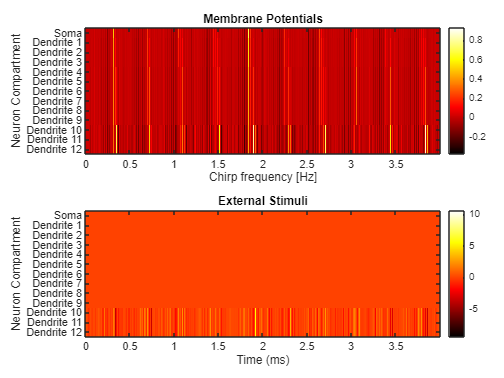

xlabel('Time (ms)');
ylabel('Neuron Compartment');
title('External Stimuli');

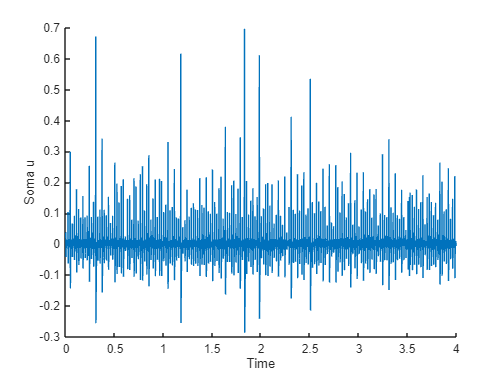


figure
hold on
plot(t, X(1, :));
ylabel('Soma u');
xlabel('Time');

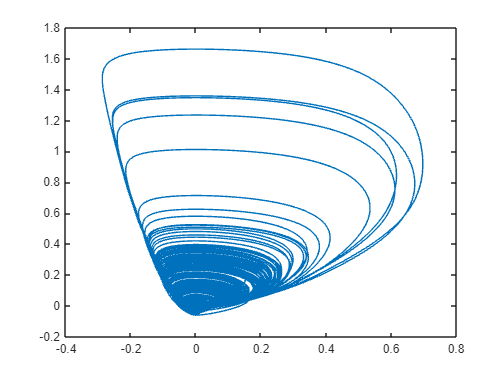


figure; plot(X(1,:), X(2,:))